% ALL THE HELPER FUNCTIONS

function dstate_dt = dynamics(state, forces, params)
    % Unpack parameters and state for clarity
    mq = params.mq;
    mb = params.mb;
    ms = params.ms;
    L = params.L;
    Ixx = params.Ixx;
    g = params.g;
    r = params.r;
    
    y = state(1);
    z = state(2);
    phi = state(3);
    theta = state(4);
    y_d = state(5);
    z_d = state(6);
    phi_d = state(7);
    theta_d = state(8);

    Fl = forces(1);
    Fr = forces(2);
  
    Ip = ms*L^2/3+mb*L^2;
    Lcg = L*(ms/2+mb)/(ms+mb);
    
    % A*x_dd = B
    
    % Dynamics derived from the pdf
    A = [ms+mb+mq 0 (ms+mb)*Lcg*cos(phi+theta) (ms+mb)*Lcg*cos(phi+theta);
        0 ms+mb+mq (ms+mb)*Lcg*sin(phi+theta) (ms+mb)*Lcg*sin(phi+theta);
        Lcg*cos(phi+theta)*(ms+mb) Lcg*sin(phi+theta)*(ms+mb) Ip Ip;
        0 0 Ixx 0];
    
    B = [-(Fl+Fr)*sin(phi)+(ms+mb)*Lcg*sin(phi+theta)*(phi_d+theta_d)^2 ;
        (Fl+Fr)*cos(phi)-(ms+mb)*Lcg*cos(phi+theta)*(phi_d+theta_d)^2-g*(ms+mb+mq) ;
        -g*Lcg*(ms+mb)*sin(phi+theta) ; 
        (Fr-Fl)*r];
    
    state_dd = A\B;

    dstate_dt = [y_d ; z_d ;phi_d ;theta_d; state_dd];
end

function [time, state_history] = run_simulation(initial_state, Fl_history, Fr_history, T, N, params)
    dt = T / N;
    time = linspace(0, T, N+1)';
    state_history = zeros(N+1, length(initial_state));
    state_history(1, :) = initial_state;
    
    current_state = initial_state(:); % Ensure it's a column vector
    
    for k = 1:N
        forces = [Fl_history(k); Fr_history(k)];
        
        dstate_dt = dynamics(current_state, forces, params); 
        
        % Simple Euler integration step
        current_state = current_state + dstate_dt * dt;
        state_history(k+1, :) = current_state';
    end
end

function [J, c, ceq] = objectiveAndConstraints(x, initial_state, target_state, T, N, params)
    forces = reshape(x, [2, N])'; % Reshape to an N x 2 matrix
    Fl_history = forces(:, 1);
    Fr_history = forces(:, 2);

    % 2. Run the simulation
    [~, state_history] = run_simulation(initial_state, Fl_history, Fr_history, T, N, params);

    % 3. Calculate Objective Function (J)
    % Minimize the sum of the control effort squared over the trajectory.
    dt = T / N;

    % Cost without the final equality constraint -> encourages angle
    % (doesn't work)
    % J = sum(sqrt((state_history(:,4).^2)-pi).^2) * dt;

    % Cost with only actuation history
    J = sum(Fl_history.^2 + Fr_history.^2) * dt;

    % Cost with actuation history + changes in actuations
    J = J+ sum((Fl_history-[Fl_history(1); Fl_history(1:end-1)]).^2 + (Fr_history-[Fr_history(1) ;Fr_history(1:end-1)]).^2) * dt;

    % 4. Calculate Inequality Constraints (c <= 0)
    z_history = state_history(:, 2); 
    z_initial = initial_state(2);
    z_upper_bound = z_initial * 1.10;
    z_lower_bound = z_initial * 0.90;

    phi_history = state_history(:,3);
    phi_upper_bound = pi/6;
    phi_lower_bound = -pi/6;

    y_history = state_history(:,1);
    y_upper_bound = 0.2;
    y_lower_bound = -0.2;

    % fmincon requires c(x) <= 0
    c1 = z_history - z_upper_bound;
    c2 = z_lower_bound - z_history;
    c3 = phi_history - phi_upper_bound;
    c4 = phi_lower_bound - phi_history;
    c5 = y_history - y_upper_bound;
    c6 = y_lower_bound - y_history;
    c = [c1; c2; c3; c4; c5; c6];

    % This hard constraint is now solely responsible for reaching the target.
    final_state = state_history(end, :);
    ceq = final_state(:) - target_state(:);
end

function [c,ceq] = constraint_wrapper(x, initial_state, target_state, T, N, params)
    [~, c, ceq] = objectiveAndConstraints(x, initial_state, target_state, T, N, params);
    % ceq = [];
end

function J = objective_wrapper(x, initial_state, target_state, T, N, params)
    [J, ~, ~] = objectiveAndConstraints(x, initial_state, target_state, T, N, params);
end

function [Fl_guess, Fr_guess] = getInitialGuess(params,T,N)
    % Initial Guess (crucial for convergence!)
    % A good guess is constant thrust to counteract gravity, then small random perturbations
    hover_force = ((params.ms+params.mb+params.mq) * params.g) / 2;
    t_guess = linspace(0, T, N); % Time vaector for the guess
    
    % Create a sinusoidal nudge force    
    nudge_amplitude = hover_force * 0.001; 
    nudge_freq = sqrt(params.g/params.L)*1; 
    
    Fl_guess = hover_force*ones([N,1]);
    Fr_guess = hover_force*ones([N,1]);

    % Chirp & increasing amplitude to encourage quadcopter to get back to
    % middle and not just drift off to infinity to one side.
    Fl_guess = hover_force + nudge_amplitude*log10(t_guess+1) .* chirp(t_guess, nudge_freq*1.8/(2*pi),3,nudge_freq*0.3/(2*pi));
    Fr_guess = hover_force - nudge_amplitude*log10(t_guess+1) .* chirp(t_guess, nudge_freq*1.8/(2*pi),3,nudge_freq*0.3/(2*pi));

    [time, state_guess] = run_simulation(initial_state, Fl_guess, Fr_guess, T, N, params);

    figure;
    plot(time(1:length(Fl_guess)),Fl_guess',time(1:length(Fr_guess)),Fr_guess')
    title("Initial Guess Forces")
    xlabel("Time (s)")
    ylabel("Force (N)")
    legend("Fl","Fr")

    figure;
    plot(time,state_guess(:,3))
    title("Initial Guess Phi Trajectory")
    xlabel("Time (s)")
    ylabel("Phi (rad)")

    figure;
    hold on
    plot(state_guess(:,1),state_guess(:,2))
    title("Initial Guess Trajectory")
    xlabel("y (m)")
    ylabel("z (m)")
    hold off
end

clear; clc; close all;

function [Fl_opt,Fr_opt, state_opt, successful] = optimization(Fl_guess, Fr_guess, params)

    T = 4.0; % Total maneuver time in seconds
    N = 100;  % Number of discretization steps
    
    y_initial = 0;
    z_initial = 1.0;
    initial_state = [y_initial, z_initial, 0, 0, 0, 0, 0, 0];
    target_state  = [y_initial, z_initial, 0, deg2rad(178), 0, 0, 0, 0.01]; % 180 deg = pi radians
    
    n_vars = 2 * N;
    
    % Bounds
    max_force = 0.3; % Newtons
    lb = zeros(n_vars, 1);
    ub = max_force * ones(n_vars, 1);

    x0 = zeros(n_vars, 1);
    x0(1:2:end) = Fl_guess; % Odd elements are Fl
    x0(2:2:end) = Fr_guess; % Even elements are Fr
    
    fprintf('Running fmincon...\n');
    options = optimoptions('fmincon', 'Display', 'iter', ...%'Algorithm', 'sqp', ...
                           'MaxFunctionEvaluations', 150000, 'MaxIterations', 1000, ...
                           'ConstraintTolerance', 1e-2, 'StepTolerance', 1e-7);
    
    objFun = @(x) objective_wrapper(x, initial_state, target_state, T, N, params);
    nonlconFun = @(x)  constraint_wrapper(x, initial_state, target_state, T, N, params);
    
    [x_optimal, fval, exitflag, output] = fmincon(objFun, x0, [], [], [], [], lb, ub, nonlconFun, options);
    
    if exitflag > 0
        fprintf('Optimization successful!\n');
        successful = true;
    else
        fprintf('Optimization failed. Exit flag: %d\n', exitflag);
        successful = false;
    end
        
    % Reshape optimal forces
    forces_opt = reshape(x_optimal, [2, N])';
    Fl_opt = forces_opt(:, 1);
    Fr_opt = forces_opt(:, 2);
    
    % Rerun simulation with optimal controls to get the final trajectory
    [time, state_opt] = run_simulation(initial_state, Fl_opt, Fr_opt, T, N, params);

    % Plotting
    figure;
    
    % Plot States
    subplot(2,1,1);
    plot(time, rad2deg(state_opt(:,4)), 'b-', 'LineWidth', 1);
    hold on;
    plot(time(end), rad2deg(target_state(4)), 'rx', 'MarkerSize', 10, 'LineWidth', 1);
    title('State Trajectories');
    ylabel('Angle (deg)');
    grid on;
    
    % Plot Controls
    subplot(2,1,2);
    stairs(time(1:end-1), Fl_opt, 'r-', 'LineWidth', 1);
    hold on;
    stairs(time(1:end-1), Fr_opt, 'g-', 'LineWidth', 1);
    title('Control Inputs (Forces)');
    xlabel('Time (s)');
    ylabel('Force (N)');
    legend('Fl (Left)', 'Fr (Right)');
    grid on;
    ylim([0, max_force * 1.1]);    
    hold off

    figure;

    % Plot Trajectory
    subplot(2,1,1);
    hold on
    plot(state_opt(:,1),state_opt(:,2))
    title("Optimized Trajectory")
    xlim([-0.1,0.1])
    ylim([0.8,1.25])
    xlabel("y (m)")
    ylabel("z (m)")
    
    % Plot Y Trajectory over time
    subplot(2,1,2);
    hold on
    plot(time,state_opt(:,1))
    title("Y Displacement over Time")
    xlabel("Time (s)")
    ylabel("Y Displacement (m)")
    hold off
end


    "Pendulum Length = "    "0.36"



Running fmincon...
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0     201    3.334131e-01    3.010e+00    1.221e-01
    1     402    3.357405e-01    6.719e-01    6.974e+01    1.309e-01
    2     604    3.354194e-01    3.333e-01    2.420e+02    3.107e-02
    3     808    3.353803e-01    3.068e-01    2.665e+02    6.011e-03
    4    1012    3.353497e-01    2.805e-01    2.882e+02    5.366e-03
    5    1216    3.353251e-01    2.548e-01    2.931e+02    4.778e-03
    6    1420    3.353057e-01    2.301e-01    2.774e+02    4.244e-03
    7    1623    3.352770e-01    1.940e-01    2.413e+02    7.525e-03
    8    1826    3.352622e-01    1.574e-01    1.986e+02    5.828e-03
    9    2028    3.352497e-01    1.074e-01    1.173e+02    9.092e-03
   10    2229    3.352533e-01    4.154e-02    1.349e+02    1.117e-02
   11    2430    3.352466e-01    4.756e-03    1.459e+02    5.298e-03
   12    2632    3.352451e-0

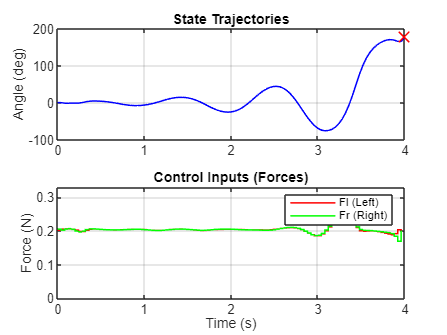

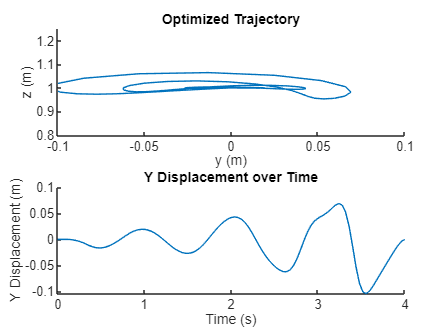

    "Pendulum Length = "    "0.37"



Running fmincon...
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0     201    3.352737e-01    2.641e+00    1.189e-01
    1     402    3.366631e-01    1.554e+00    5.907e+02    5.059e-02
    2     603    3.360009e-01    9.820e-01    3.327e+02    6.122e-02
    3     804    3.357824e-01    5.917e-02    2.325e+02    1.216e-02
    4    1006    3.354884e-01    2.973e-03    8.145e+01    2.118e-02
    5    1211    3.354790e-01    3.376e-03    7.899e+01    1.727e-03
    6    1418    3.354813e-01    2.768e-04    1.050e-01    3.448e-03
    7    1619    3.354563e-01    1.396e-02    2.595e+00    2.708e-03
    8    1821    3.353889e-01    5.582e-02    2.186e+01    1.386e-02
    9    2022    3.354046e-01    1.493e-01    1.294e+01    1.072e-02
   10    2223    3.354539e-01    2.979e-02    2.202e+01    7.578e-03
   11    2424    3.354741e-01    1.286e-02    2.309e+01    5.646e-03
   12    2625    3.354974e-0

   26    5446    3.355367e-01    6.338e-09    2.095e-02    5.666e-07
   27    5647    3.355367e-01    1.752e-11    4.305e-03    1.818e-09

Feasible point with lower objective function value found, but optimality criteria not satisfied. See output.bestfeasible..


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<

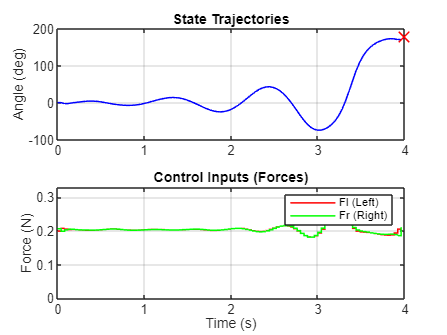

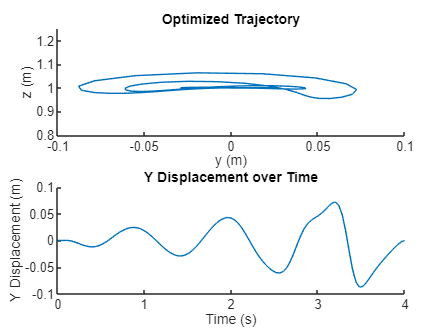

    "Pendulum Length = "    "0.38"



Running fmincon...
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0     201    3.355367e-01    5.134e+00    1.165e-01
    1     402    3.401626e-01    2.926e-01    1.157e+03    8.732e-02
    2     603    3.353329e-01    2.849e-02    2.902e+02    9.249e-02
    3     806    3.353894e-01    2.010e-02    2.410e+02    4.284e-03
    4    1010    3.354087e-01    1.715e-02    2.130e+02    1.957e-03
    5    1216    3.354647e-01    1.170e-02    1.050e-01    1.553e-03
    6    1418    3.355506e-01    9.850e-03    1.370e+01    2.257e-03
    7    1621    3.355633e-01    9.345e-03    1.990e+01    1.209e-03
    8    1824    3.355680e-01    9.384e-03    2.061e+01    1.352e-03
    9    2028    3.355676e-01    8.875e-03    2.125e+01    7.516e-04
   10    2232    3.355663e-01    8.437e-03    2.191e+01    7.844e-04
   11    2436    3.355645e-01    8.043e-03    2.260e+01    8.125e-04
   12    2640    3.355622e-0

   56   11560    3.354317e-01    9.288e-09    3.967e+00    1.495e-06


   57   11762    3.354317e-01    8.941e-08    3.968e+00    1.053e-05


   58   11964    3.354317e-01    8.955e-09    3.969e+00    3.539e-06


   59   12170    3.354317e-01    1.300e-11    4.347e-03    3.288e-09

Feasible point with lower objective function value found, but optimality criteria not satisfied. See output.bestfeasible..


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<

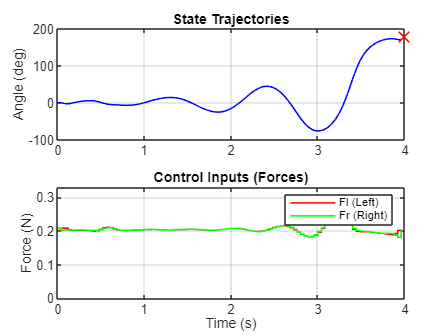

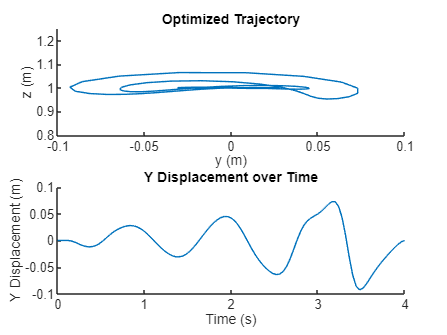

    "Pendulum Length = "    "0.39"



Running fmincon...
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0     201    3.354317e-01    4.568e+00    1.134e-01
    1     402    3.397732e-01    1.093e+00    1.534e+03    7.997e-02
    2     603    3.358450e-01    6.005e-02    4.721e+02    7.879e-02
    3     807    3.358370e-01    5.483e-02    4.384e+02    1.779e-03
    4    1012    3.358541e-01    1.875e-02    1.045e-01    3.219e-03
    5    1213    3.358585e-01    8.526e-03    1.588e+01    3.375e-03
    6    1420    3.357213e-01    5.276e-04    2.157e-02    7.993e-03
    7    1621    3.356489e-01    3.127e-04    5.861e-01    2.188e-03
    8    1827    3.355073e-01    4.826e-04    3.919e-04    4.768e-03
    9    2038    3.352075e-01    1.797e-03    6.454e-02    1.139e-02
   10    2241    3.350693e-01    1.224e-03    1.249e-01    2.939e-03
   11    2450    3.348347e-01    1.980e-03    2.239e-01    1.079e-02
   12    2662    3.346359e-0

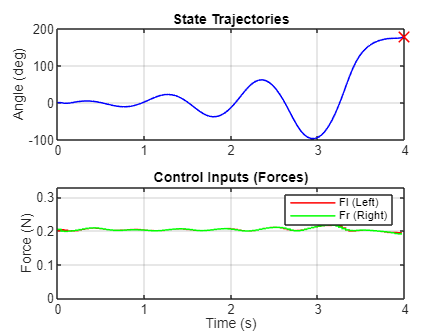

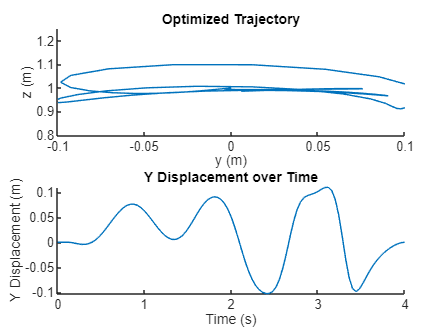

    "Pendulum Length = "    "0.4"



Running fmincon...
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0     201    3.335140e-01    2.370e+00    1.228e-01
    1     402    3.357911e-01    8.000e-01    4.669e+02    1.277e-01
    2     603    3.355009e-01    1.349e-01    2.205e+02    6.546e-02
    3     804    3.359880e-01    3.372e-02    6.923e+01    1.103e-02
    4    1005    3.360742e-01    3.064e-03    4.101e+01    4.998e-03
    5    1207    3.360237e-01    1.312e-04    3.164e+01    4.317e-03
    6    1416    3.359759e-01    3.231e-04    1.029e-01    3.771e-03
    7    1617    3.359513e-01    6.898e-03    3.442e+00    1.759e-03
    8    1819    3.358403e-01    1.512e-02    1.719e+01    8.437e-03
    9    2020    3.358194e-01    4.442e-02    1.978e+01    5.360e-03
   10    2221    3.358060e-01    1.057e-02    2.580e+01    3.342e-03
   11    2422    3.358014e-01    2.701e-03    2.652e+01    2.145e-03
   12    2623    3.358011e-0

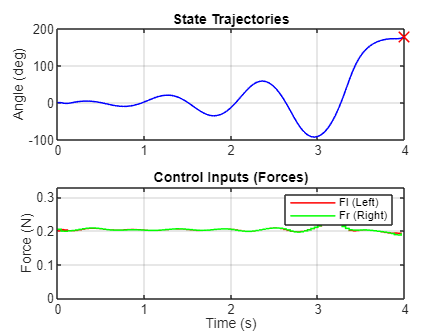

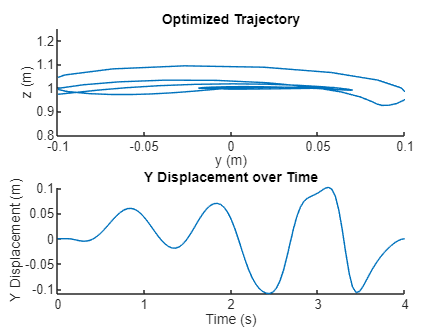

    "Pendulum Length = "    "0.41"



Running fmincon...
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0     201    3.337227e-01    1.760e+00    1.234e-01
    1     406    3.339085e-01    1.682e+00    1.037e+01    1.353e-02
    2     610    3.341142e-01    1.529e+00    2.791e+01    1.094e-02
    3     814    3.343169e-01    1.392e+00    3.330e+01    9.696e-03
    4    1018    3.345104e-01    1.260e+00    3.829e+01    8.835e-03
    5    1222    3.346910e-01    1.136e+00    4.323e+01    7.967e-03
    6    1425    3.350283e-01    9.509e-01    4.151e+01    1.443e-02
    7    1628    3.353159e-01    7.784e-01    5.841e+01    1.203e-02
    8    1830    3.357832e-01    5.006e-01    8.679e+01    1.901e-02
    9    2031    3.363218e-01    7.132e-02    1.757e+02    2.210e-02
   10    2232    3.362653e-01    2.139e-03    1.889e+02    5.918e-03
   11    2434    3.362168e-01    1.392e-04    1.016e+02    5.815e-03
   12    2641    3.362138e-0

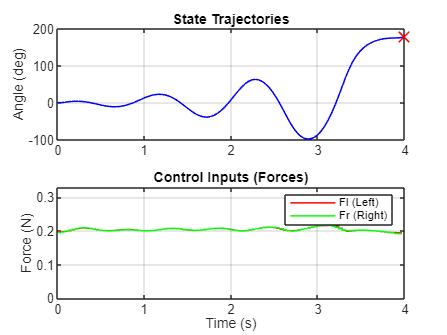

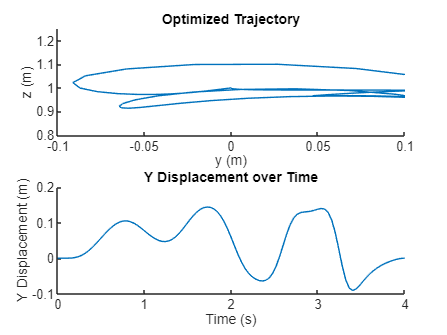

    "Pendulum Length = "    "0.42"



Running fmincon...
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0     201    3.335467e-01    2.117e+00    1.248e-01
    1     404    3.344286e-01    1.960e+00    3.636e+01    6.976e-02
    2     605    3.370107e-01    6.274e-01    7.412e+02    7.862e-02
    3     806    3.362384e-01    3.048e-01    4.511e+01    3.574e-02
    4    1007    3.362432e-01    1.399e-02    9.646e+01    3.938e-03
    5    1209    3.362219e-01    8.158e-04    3.277e+01    6.237e-03
    6    1411    3.362338e-01    2.033e-03    3.139e+01    5.364e-03
    7    1615    3.362404e-01    2.127e-03    2.958e+01    1.547e-03
    8    1822    3.362556e-01    1.294e-04    1.022e-01    3.058e-03
    9    2023    3.362567e-01    2.048e-03    1.432e+00    1.242e-03
   10    2224    3.362727e-01    4.639e-02    4.362e+00    5.924e-03
   11    2425    3.363172e-01    1.882e-02    7.441e+00    4.449e-03
   12    2626    3.363515e-0

   38    7872    3.362397e-01    1.792e-08    3.735e+00    2.547e-06


   39    8074    3.362397e-01    1.218e-08    3.735e+00    1.534e-06
   40    8275    3.362397e-01    7.830e-11    4.178e-03    3.131e-09

Feasible point with lower objective function value found, but optimality criteria not satisfied. See output.bestfeasible..


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<

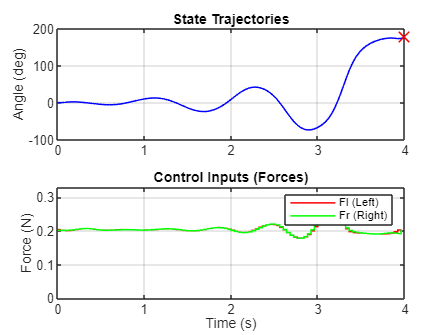

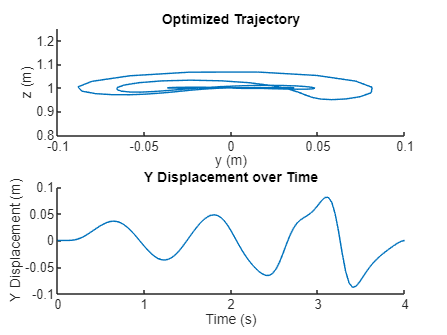

    "Pendulum Length = "    "0.43"



Running fmincon...
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0     201    3.362397e-01    5.663e+00    1.154e-01
    1     402    3.427505e-01    1.092e+00    2.366e+03    1.042e-01
    2     603    3.360657e-01    1.236e-01    4.048e+02    1.170e-01
    3     805    3.362699e-01    4.409e-02    2.884e+02    8.860e-03
    4    1007    3.363652e-01    1.598e-02    1.582e+02    5.531e-03
    5    1208    3.364662e-01    7.446e-03    4.197e+01    6.811e-03
    6    1409    3.364771e-01    5.639e-03    4.796e+01    3.551e-03
    7    1610    3.364769e-01    1.464e-03    5.400e+01    2.202e-03
    8    1812    3.364909e-01    6.597e-05    5.886e+01    1.872e-03
    9    2014    3.364902e-01    3.599e-05    6.319e+01    1.398e-03
   10    2216    3.364947e-01    1.391e-05    6.592e+01    9.570e-04
   11    2423    3.364949e-01    2.769e-06    1.067e-01    7.214e-04
   12    2624    3.364807e-0

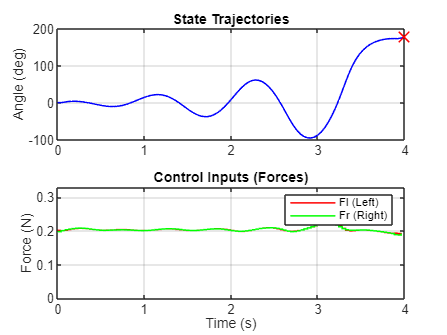

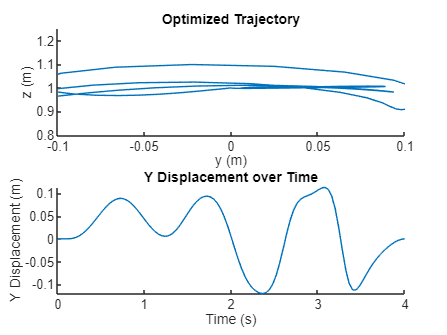

    "Pendulum Length = "    "0.44"



Running fmincon...
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0     201    3.337304e-01    1.611e+00    1.240e-01
    1     402    3.356703e-01    6.050e-01    1.017e+02    1.321e-01
    2     604    3.361035e-01    7.976e-02    1.965e+02    2.845e-02
    3     806    3.363230e-01    4.671e-02    2.588e+02    1.840e-02
    4    1008    3.364646e-01    4.312e-02    2.084e+02    1.055e-02
    5    1210    3.365382e-01    3.105e-02    1.299e+02    6.077e-03
    6    1412    3.365676e-01    2.156e-02    8.391e+01    3.952e-03
    7    1614    3.365727e-01    1.450e-02    8.951e+01    2.974e-03
    8    1815    3.365632e-01    8.241e-03    1.045e+02    4.637e-03
    9    2016    3.365438e-01    1.190e-03    1.089e+02    2.353e-03
   10    2217    3.365355e-01    2.112e-04    1.111e+02    1.094e-03
   11    2418    3.365319e-01    2.201e-05    1.120e+02    5.349e-04
   12    2620    3.365311e-0

   28    5848    3.365298e-01    2.669e-06    1.129e+02    3.662e-05


   29    6049    3.365298e-01    2.538e-06    1.129e+02    2.932e-05


   30    6250    3.365299e-01    1.615e-06    1.129e+02    2.571e-05



                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
   31    6451    3.365299e-01    1.495e-06    1.129e+02    2.164e-05


   32    6652    3.365299e-01    1.137e-06    1.129e+02    2.034e-05


   33    6853    3.365299e-01    8.325e-07    1.130e+02    1.568e-05


   34    7055    3.365299e-01    5.478e-08    1.130e+02    1.775e-05


   35    7261    3.365299e-01    1.298e-10    1.077e-01    1.298e-08

Feasible point with lower objective function value found, but optimality criteria not satisfied. See output.bestfeasible..


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<

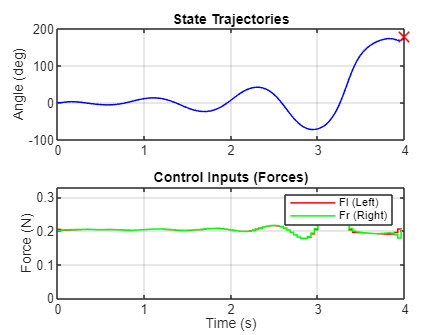

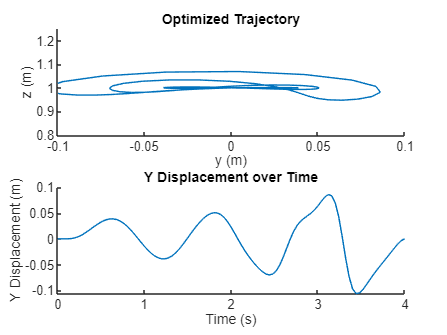

    "Pendulum Length = "    "0.45"



Running fmincon...
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0     201    3.365299e-01    3.838e+00    1.173e-01
    1     402    3.403618e-01    5.722e-01    1.331e+03    7.489e-02
    2     603    3.370522e-01    6.789e-02    5.334e+02    7.852e-02
    3     805    3.371025e-01    4.510e-02    4.788e+02    8.273e-03
    4    1011    3.371724e-01    2.203e-02    1.049e-01    6.000e-03
    5    1212    3.371223e-01    8.111e-03    1.456e+01    3.265e-03
    6    1419    3.370357e-01    4.434e-04    2.186e-02    6.804e-03
    7    1620    3.369402e-01    6.744e-04    2.829e-01    2.201e-03
    8    1826    3.367556e-01    1.063e-03    4.217e-04    5.204e-03
    9    2031    3.366785e-01    2.560e-03    1.951e-02    1.921e-03
   10    2236    3.362492e-01    4.488e-03    1.006e-01    1.326e-02
   11    2441    3.359074e-01    7.794e-03    2.128e-01    1.005e-02
   12    2646    3.356929e-0

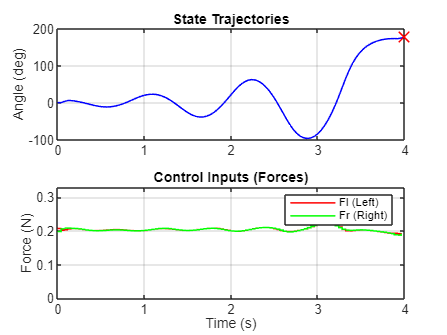

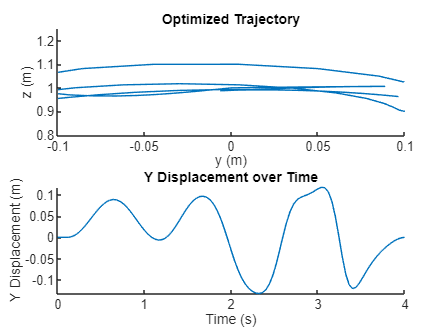

    "Pendulum Length = "    "0.46"



Running fmincon...
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0     201    3.338154e-01    1.885e+00    1.252e-01
    1     402    3.361252e-01    1.894e+00    9.732e+01    1.425e-01
    2     603    3.373376e-01    4.045e-02    7.960e+01    8.254e-02
    3     805    3.373554e-01    3.712e-02    1.016e+02    1.443e-02
    4    1009    3.373697e-01    3.497e-02    1.036e+02    2.659e-03
    5    1213    3.373840e-01    3.311e-02    1.060e+02    2.494e-03
    6    1417    3.373981e-01    3.143e-02    1.088e+02    2.331e-03
    7    1621    3.374118e-01    2.986e-02    1.120e+02    2.174e-03
    8    1825    3.374248e-01    2.841e-02    1.154e+02    2.032e-03
    9    2029    3.374372e-01    2.706e-02    1.191e+02    1.905e-03
   10    2233    3.374489e-01    2.583e-02    1.227e+02    1.794e-03
   11    2437    3.374597e-01    2.470e-02    1.258e+02    1.697e-03
   12    2641    3.374698e-0

   54   11127    3.365196e-01    3.109e-06    6.121e-01    3.416e-04


   55   11330    3.365198e-01    3.836e-06    6.161e-01    4.042e-04


   56   11532    3.365207e-01    7.964e-06    6.397e-01    1.256e-03


   57   11734    3.365198e-01    1.303e-05    6.208e-01    1.079e-03
   58   11939    3.365193e-01    1.572e-05    6.178e-01    2.704e-04
   59   12145    3.365193e-01    1.028e-07    9.734e-04    2.174e-06


   60   12346    3.360345e-01    9.962e-03    9.910e-02    1.632e-02



                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
   61   12547    3.354403e-01    2.231e-02    4.241e-01    2.140e-02


   62   12750    3.353690e-01    1.369e-02    4.864e-01    9.908e-03


   63   12951    3.355729e-01    1.235e-02    6.014e-01    1.131e-02


   64   13155    3.355705e-01    1.171e-02    5.896e-01    2.309e-03


   65   13356    3.354823e-01    1.090e-02    5.054e-01    8.303e-03


   66   13557    3.355153e-01    3.690e-03    5.091e-01    3.837e-03


   67   13759    3.355293e-01    3.571e-03    5.052e-01    1.833e-03


   68   13960    3.355350e-01    2.217e-03    4.866e-01    4.361e-03


   69   14162    3.355228e-01    1.617e-03    4.905e-01    2.139e-03


   70   14364    3.355411e-01    6.037e-04    4.725e-01    4.261e-03


   71   14565    3.355106e-01    7.371e-04    4.626e-01    4.901e-03


   72   14769    3.355109e-01    6.642e-04    4.669e-01    8.292e-04


   73   14970    3.355175e-01    8.761e-04    4.703e-01    1.799e-03


   74   15172    3.355210e-01    3.143e-04    4.619e-01    2.313e-03


   75   15374    3.355219e-01    1.130e-04    4.675e-01    1.218e-03


   76   15578    3.355200e-01    1.213e-04    4.662e-01    8.390e-04


   77   15784    3.355208e-01    6.516e-08    1.950e-01    1.675e-05


   78   15990    3.355208e-01    8.716e-10    1.950e-01    2.116e-08

Feasible point with lower objective function value found, but optimality criteria not satisfied. See output.bestfeasible..


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<

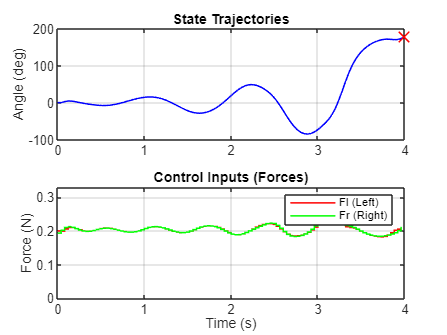

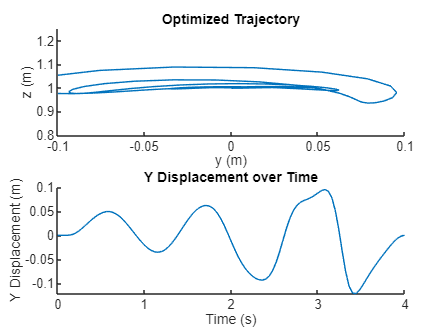

    "Pendulum Length = "    "0.47"



Running fmincon...
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0     201    3.355208e-01    1.186e+00    1.215e-01
    1     403    3.361923e-01    1.718e-01    2.309e+02    4.574e-02
    2     604    3.370637e-01    8.362e-02    1.978e+02    4.373e-02
    3     805    3.375173e-01    7.202e-03    1.256e+02    2.171e-02
    4    1009    3.375167e-01    6.690e-03    1.233e+02    1.557e-03
    5    1213    3.375174e-01    6.600e-03    1.215e+02    1.549e-03
    6    1418    3.375334e-01    3.128e-03    1.057e-01    2.573e-03
    7    1619    3.375197e-01    1.703e-03    5.551e+00    2.379e-03
    8    1821    3.374995e-01    2.334e-03    6.712e+00    1.076e-02
    9    2023    3.375420e-01    1.237e-04    9.001e+00    4.776e-03
   10    2224    3.375502e-01    7.101e-04    1.026e+01    2.466e-03
   11    2426    3.375579e-01    4.809e-04    1.024e+01    7.544e-04
   12    2628    3.375629e-0

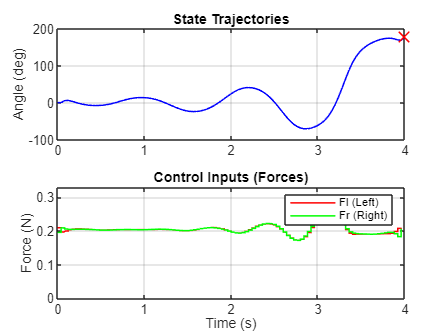

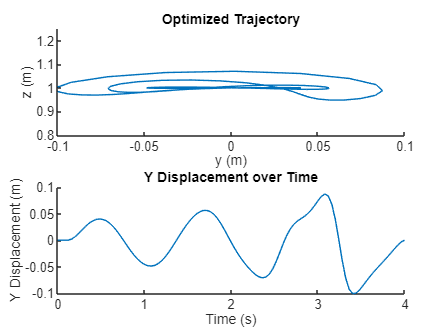

    "Pendulum Length = "    "0.48"



Running fmincon...
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0     201    3.375795e-01    5.048e+00    1.139e-01
    1     402    3.433182e-01    6.396e-01    2.125e+03    1.022e-01
    2     603    3.372773e-01    2.455e-01    7.143e+02    1.159e-01
    3     805    3.374810e-01    8.244e-02    4.888e+02    1.006e-02
    4    1007    3.375415e-01    1.901e-02    2.220e+02    6.747e-03
    5    1208    3.376208e-01    9.530e-03    1.570e+02    1.046e-02
    6    1410    3.376776e-01    3.094e-03    1.537e+02    6.781e-03
    7    1612    3.376804e-01    1.435e-03    1.495e+02    5.135e-03
    8    1814    3.377072e-01    5.537e-04    1.461e+02    4.110e-03
    9    2016    3.377103e-01    1.772e-04    1.456e+02    2.809e-03
   10    2218    3.377242e-01    6.193e-05    1.504e+02    2.210e-03
   11    2420    3.377262e-01    2.480e-05    1.549e+02    1.436e-03
   12    2622    3.377338e-0

   41    8483    3.373329e-01    2.917e-07    2.038e+00    8.732e-06
   42    8684    3.373329e-01    1.471e-10    4.333e-03    8.960e-08

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>
Optimization successful!


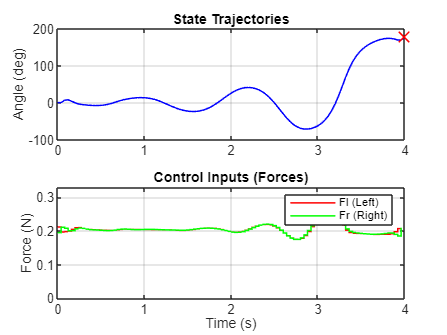

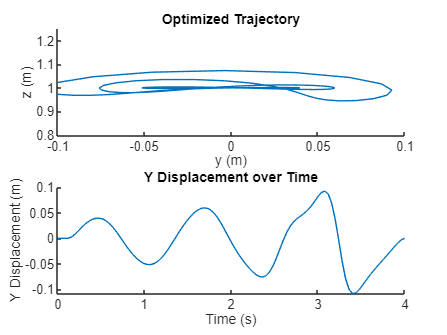

    "Pendulum Length = "    "0.49"



Running fmincon...
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0     201    3.373329e-01    3.948e+00    1.154e-01
    1     402    3.418193e-01    7.306e-01    1.835e+03    8.461e-02
    2     603    3.379914e-01    8.904e-02    7.168e+02    8.791e-02
    3     805    3.379985e-01    3.306e-02    5.829e+02    7.733e-03
    4    1007    3.379431e-01    1.470e-02    3.136e+02    6.993e-03
    5    1210    3.379249e-01    1.249e-02    2.123e+02    2.845e-03
    6    1412    3.378961e-01    9.661e-03    4.887e+01    5.402e-03
    7    1613    3.378758e-01    4.512e-03    7.124e+01    8.818e-03
    8    1817    3.378780e-01    4.142e-03    7.298e+01    7.024e-04
    9    2022    3.378802e-01    3.803e-03    7.467e+01    6.838e-04
   10    2224    3.379049e-01    1.395e-03    8.772e+01    5.166e-03
   11    2426    3.379159e-01    3.802e-04    9.681e+01    3.649e-03
   12    2628    3.379262e-0

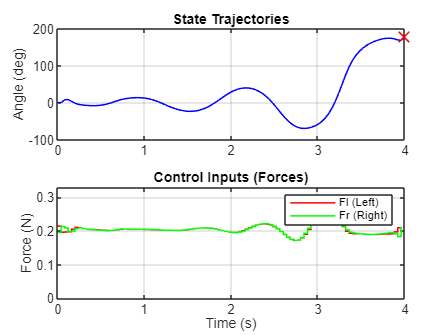

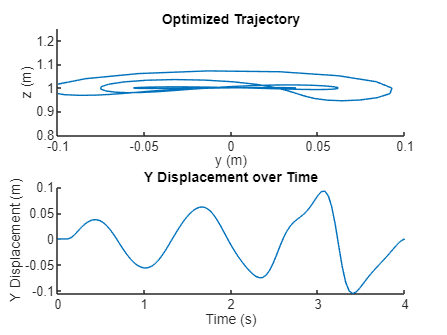

    "Pendulum Length = "    "0.5"



Running fmincon...
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0     201    3.379502e-01    4.094e+00    1.139e-01
    1     402    3.423033e-01    6.443e-01    1.919e+03    8.893e-02
    2     603    3.381914e-01    1.741e-01    7.609e+02    9.331e-02
    3     805    3.382029e-01    6.643e-02    5.578e+02    8.647e-03
    4    1007    3.381479e-01    1.337e-02    2.745e+02    6.510e-03
    5    1208    3.381016e-01    7.538e-03    1.090e+02    1.016e-02
    6    1410    3.381364e-01    1.069e-03    1.056e+02    6.391e-03
    7    1612    3.381311e-01    3.991e-04    1.156e+02    4.049e-03
    8    1814    3.381504e-01    1.290e-04    1.217e+02    3.210e-03
    9    2016    3.381502e-01    3.587e-05    1.280e+02    1.938e-03
   10    2218    3.381605e-01    1.155e-05    1.308e+02    1.560e-03
   11    2420    3.381605e-01    4.091e-06    1.339e+02    8.886e-04
   12    2622    3.381658e-0

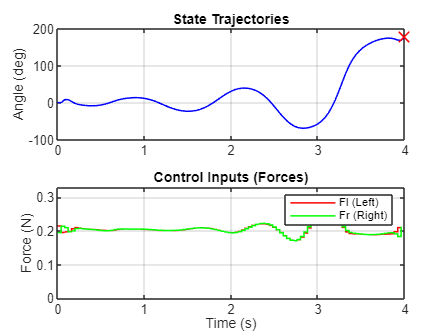

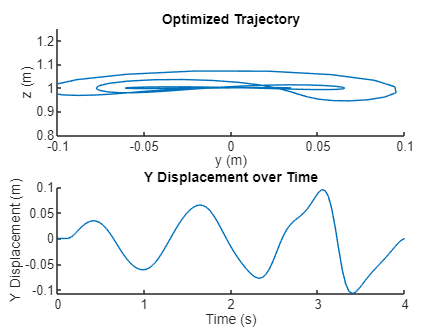

FL_opt = load('data/fl_opt_178deg.mat').FL_opt;
FR_opt = load('data/fr_opt_178deg.mat').FR_opt;
state_opt = load('data/state_optimal_178.mat').STATE_opt;

FL_opt = load('data/fl_opt_0.35.mat').fl35;
FR_opt = load('data/fr_opt_0.35.mat').fr35;
state_opt = load('data/state_optimal_0.35.mat').state35;

STATE_opt(:,:,1) = state_opt;

params.mq = 0.029; % kg
params.mb = 0.01; % kg
params.ms = 0.0025; % kg
params.Ixx = 6.410179e-06; % kg m2
params.g = 9.81; % kg/m2
params.r = 0.05665/2; % m

% for length=0.30:0.01:0.30
%     disp(["Pendulum Length = " num2str(length)])
%     params.L = length; % m
%     [fl_opt,fr_opt, state_opt, successful] = optimization(FL_opt(:,end),FR_opt(:,end), params);
%     if (~successful)
%         break
%     end
%     FL_opt = fl_opt;
%     FR_opt = fr_opt;
%     STATE_opt = state_opt;
% end

for length=0.36:0.01:0.50
    disp(["Pendulum Length = " num2str(length)])
    params.L = length; % m
    [fl_opt,fr_opt, state_opt, successful] = optimization(FL_opt(:,end),FR_opt(:,end), params);
    if (~successful)
        break
    end
    FL_opt = [FL_opt , fl_opt];
    FR_opt = [FR_opt, fr_opt];
    STATE_opt = cat(3,STATE_opt, state_opt);
end


% for length=0.29:-0.01:0.15
%     disp(["Pendulum Length = " num2str(length)])
%     params.L = length; % m
%     [fl_opt,fr_opt, state_opt, successful] = optimization(FL_opt(:,1),FR_opt(:,1), params);
%     if (~successful)
%         break
%     end
%     FL_opt = [fl_opt, FL_opt];
%     FR_opt = [fr_opt, FR_opt];
%     STATE_opt = cat(3,state_opt, STATE_opt);
% end

FL_opt

FL_opt =     0.1995    0.2020    0.1993    0.2013    0.2005    0.2003    0.1979    0.2040    0.2018    0.2046    0.2074    0.2003    0.2095    0.2117    0.2142    0.2147
    0.2026    0.2056    0.2078    0.2086    0.2036    0.2040    0.1977    0.2020    0.2008    0.2023    0.2023    0.1995    0.1969    0.1968    0.1962    0.1954
    0.2033    0.2060    0.2054    0.2083    0.2021    0.2027    0.1988    0.2009    0.2020    0.2023    0.2036    0.2058    0.1998    0.1978    0.1970    0.1973
    0.2029    0.2060    0.2044    0.2033    0.2002    0.2007    0.2011    0.2013    0.2041    0.2029    0.2062    0.2105    0.2036    0.1995    0.1971    0.1984
    0.2028    0.2052    0.2047    0.2013    0.1999    0.2005    0.2039    0.2025    0.2061    0.2033    0.2074    0.2102    0.2054    0.2048    0.2053    0.2064
    0.2030    0.2024    0.2041    0.2016    0.2011    0.2018    0.2064    0.2042    0.2074    0.2036    0.2070    0.2070    0.2060    0.2094    0.2107    0.2099
    0.2032    0.1983    0

FR_opt

FR_opt =     0.2037    0.2054    0.2066    0.2085    0.2047    0.2050    0.1953    0.2020    0.1979    0.2014    0.1983    0.1935    0.1957    0.1952    0.1953    0.1951
    0.2012    0.2024    0.1992    0.2019    0.1994    0.1994    0.1970    0.2016    0.2011    0.2033    0.2062    0.2021    0.2092    0.2111    0.2134    0.2141
    0.2012    0.2055    0.2032    0.2039    0.1987    0.1991    0.1994    0.2018    0.2036    0.2036    0.2085    0.2103    0.2058    0.2081    0.2091    0.2098
    0.2018    0.2070    0.2055    0.2026    0.1996    0.2003    0.2020    0.2024    0.2054    0.2038    0.2083    0.2128    0.2046    0.2006    0.1978    0.1977
    0.2020    0.2048    0.2052    0.2024    0.2007    0.2015    0.2048    0.2033    0.2069    0.2041    0.2078    0.2107    0.2048    0.2010    0.1995    0.2003
    0.2023    0.1997    0.2038    0.2028    0.2020    0.2029    0.2072    0.2047    0.2080    0.2042    0.2072    0.2068    0.2049    0.2061    0.2071    0.2070
    0.2026    0.1968    0

STATE_opt

STATE_opt = STATE_opt(:,:,1) =

         0    1.0000         0         0         0         0         0         0
         0    1.0000         0         0         0   -0.0038    0.7514   -0.7514
         0    0.9998    0.0301   -0.0301         0   -0.0070    0.4957   -0.4957
         0    0.9996    0.0499   -0.0499   -0.0163   -0.0097    0.1315   -0.0831
   -0.0007    0.9992    0.0551   -0.0532   -0.0434   -0.0125   -0.0653    0.1941
   -0.0024    0.9987    0.0525   -0.0454   -0.0730   -0.0154   -0.1980    0.4124
   -0.0053    0.9981    0.0446   -0.0290   -0.1005   -0.0179   -0.3321    0.6198
   -0.0093    0.9973    0.0313   -0.0042   -0.1224   -0.0198   -0.4359    0.7704
   -0.0142    0.9966    0.0139    0.0267   -0.1352   -0.0218   -0.4411    0.7823
   -0.0196    0.9957   -0.0038    0.0579   -0.1366   -0.0244   -0.3971    0.6953
   -0.0251    0.9947   -0.0196    0.0858   -0.1263   -0.0279   -0.3057    0.5110
   -0.0301    0.9936   -0.0319    0.1062   -0.1056   -0.0316   -0.1937    0.2